# Eigenvalue Decomposition

clear, close all, format short

## Computing the EVD in MATLAB

The following is a diagonalizable matrix. 

A = [2 1; 1 1]

A =      2     1
     1     1


E = eig(A)

E =     0.3820
    2.6180


[V, D] = eig(A)

V =     0.5257   -0.8507
   -0.8507   -0.5257


D =     0.3820         0
         0    2.6180


norm(A - V*D/V) % /V is right-multiplication by V^{-1}

ans = 3.1402e-16

- `\`: left-multiplication by inverse, e.g. `A\b` $= A^{-1}b$

- `/`: right-multiplication by inverse, e.g. `D/V` $= D V^{-1}$

`eig` also works for nondiagonalizable matrices.

[V, D] = eig([1 1; 0 1])

V =     1.0000   -1.0000
         0    0.0000


D =      1     0
     0     1


rank(V)

ans = 1

### Visualization of eigenvalues (spectrum)

A = randn(500);
E = eig(A)

E =  -22.6261 + 0.0000i
  21.4735 + 7.3477i
  21.4735 - 7.3477i
  19.6614 +10.9416i
  19.6614 -10.9416i
   1.0996 +22.1662i
   1.0996 -22.1662i
  -6.4675 +21.3858i
  -6.4675 -21.3858i
 -18.8723 +11.7434i


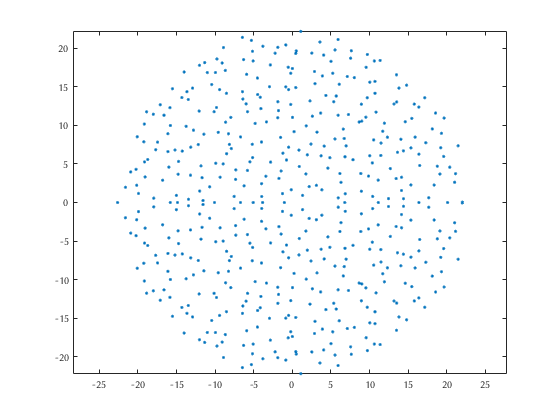

plot(real(E), imag(E), '.')
axis equal

## Conditioning

Let's construct a tridiagonal matrix with known eigenvalues.

n = 15;
lambda = (1:n)';
A = triu( ones(n,1) * lambda' )

Let's estimate the (absolute) condition number of the eigenvalues using the Bauer-Fike theorem.

[V, ~] = eig(A);
kappa = cond(V)

Experiment with perturbations of size $\sim 10^{-7}$.

for k = 1:10
    dA = randn(n);
    dA = 1e-7*dA/norm(dA);  % remember this trick?
    mu = eig(A+dA);
    norm( sort(mu) - lambda, 'inf' )
end